%% Vegyes Modulációs (BPSK-QPSK) Konvolúciós Kódolás Szimuláció
% Ez a szkript bemutatja az "Egyenlőtlen Hibavédelem" (UEP) módszereit.
% 3 rendszert versenyeztet RSC (Rekurzív) konvolúciós kódolóval:
% 1. Tiszta QPSK
% 2. BPSK a széleken (Anchor effektus)
% 3. Elosztott BPSK szegmensek (Periodikus horgonyok a hibaterjedés ellen)

clear; clc; close all;

%% 1. Rendszer paraméterek
K = 7; % Kényszerhossz
% RSC (Recursive Systematic Convolutional) kódoló
% Ez sokkal közelebb áll az LTE Turbo kódok építőelemeihez!
trellis = poly2trellis(K, [147 115], 147); 

dataLen = 1000;         % Hasznos adatbitek száma (NINCSENEK tail bitek!)
% R=1/2 miatt a kódolt bitszám pontosan a duplája:
codedLen = dataLen * 2; % 1000 * 2 = 2000 kódolt bit

snr_dB_array = 0:0.5:4.5; % SNR tartomány
max_keret = 1000;         % Szimulált keretek SNR pontonként

% Eredménytárolók
ber_qpsk  = zeros(size(snr_dB_array));
ber_edge  = zeros(size(snr_dB_array));
ber_distr = zeros(size(snr_dB_array));

fprintf('--- Szimuláció indítása: Különböző UEP elrendezések (RSC Kóddal) ---\n');

--- Szimuláció indítása: Különböző UEP elrendezések (RSC Kóddal) ---


fprintf('Kódolt kerethossz: %d bit (400 BPSK és 1600 QPSK bit)\n\n', codedLen);

Kódolt kerethossz: 2000 bit (400 BPSK és 1600 QPSK bit)




for snr_idx = 1:length(snr_dB_array)
    snr = snr_dB_array(snr_idx);
    hiba_qpsk = 0; hiba_edge = 0; hiba_distr = 0;
    
    nv = 10^(-snr/10); % Zajteljesítmény LLR-hez
    
    for k = 1:max_keret
        %% --- ADATGENERÁLÁS ÉS KÓDOLÁS ---
        data = randi([0 1], dataLen, 1);
        
        % Konvolúciós kódolás (Közvetlenül az adatot, extra farokbitek NÉLKÜL)
        codedData = convenc(data, trellis); % 2000 bit
        
        %% --- 1. RENDSZER: TISZTA QPSK (REFERENCIA) ---
        cD_qpsk = reshape(codedData, 2, [])';
        tx_qpsk = pskmod(bi2de(cD_qpsk, "left-msb"), 4, pi/4);
        rx_qpsk = awgn(tx_qpsk, snr, 'measured');
        llr_qpsk_pairs = pskdemod(rx_qpsk, 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        
        % A TE BEÁLLÍTÁSOD: 'trunc' a farokbitek hiánya miatt!
        dec_qpsk_full = vitdec(llr_qpsk_pairs(:), trellis, 100, 'trunc', 'unquant');
        hiba_qpsk = hiba_qpsk + biterr(data, dec_qpsk_full);
        
        %% --- 2. RENDSZER: SZÉLEKEN BPSK ---
        % Felosztás: 200 BPSK | 1600 QPSK | 200 BPSK
        tx_edge = [ pskmod(codedData(1:200), 2, 0); ...
                    pskmod(bi2de(reshape(codedData(201:1800), 2, [])', "left-msb"), 4, pi/4); ...
                    pskmod(codedData(1801:2000), 2, 0) ];
                
        rx_edge = awgn(tx_edge, snr, 'measured');
        
        % Demoduláció szegmensenként
        llr_edge_1 = pskdemod(rx_edge(1:200), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        llr_edge_2 = pskdemod(rx_edge(201:1000), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv); % 800 szimbólum = 1600 bit
        llr_edge_3 = pskdemod(rx_edge(1001:1200), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        
        llr_edge_stream = [llr_edge_1; llr_edge_2(:); llr_edge_3];
        % Szintén 'trunc' mód
        dec_edge_full = vitdec(llr_edge_stream, trellis, 100, 'trunc', 'unquant');
        hiba_edge = hiba_edge + biterr(data, dec_edge_full);
        
        %% --- 3. RENDSZER: ELOSZTOTT BPSK (Periodikus horgonyok) ---
        % Felosztás 5 blokkba:
        % 80 BPSK | 400 QPSK | 80 BPSK | 400 QPSK | 80 BPSK | 400 QPSK | 80 BPSK | 400 QPSK | 80 BPSK
        
        tx_d1 = pskmod(codedData(1:80), 2, 0);
        tx_d2 = pskmod(bi2de(reshape(codedData(81:480), 2, [])', "left-msb"), 4, pi/4);
        tx_d3 = pskmod(codedData(481:560), 2, 0);
        tx_d4 = pskmod(bi2de(reshape(codedData(561:960), 2, [])', "left-msb"), 4, pi/4);
        tx_d5 = pskmod(codedData(961:1040), 2, 0);
        tx_d6 = pskmod(bi2de(reshape(codedData(1041:1440), 2, [])', "left-msb"), 4, pi/4);
        tx_d7 = pskmod(codedData(1441:1520), 2, 0);
        tx_d8 = pskmod(bi2de(reshape(codedData(1521:1920), 2, [])', "left-msb"), 4, pi/4);
        tx_d9 = pskmod(codedData(1921:2000), 2, 0);
        
        tx_distr = [tx_d1; tx_d2; tx_d3; tx_d4; tx_d5; tx_d6; tx_d7; tx_d8; tx_d9];
        rx_distr = awgn(tx_distr, snr, 'measured');
        
        ll1 = pskdemod(rx_distr(1:80), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll2 = pskdemod(rx_distr(81:280), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll3 = pskdemod(rx_distr(281:360), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll4 = pskdemod(rx_distr(361:560), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll5 = pskdemod(rx_distr(561:640), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll6 = pskdemod(rx_distr(641:840), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll7 = pskdemod(rx_distr(841:920), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll8 = pskdemod(rx_distr(921:1120), 4, pi/4, 'OutputType', 'llr', 'NoiseVariance', nv);
        ll9 = pskdemod(rx_distr(1121:1200), 2, 0, 'OutputType', 'llr', 'NoiseVariance', nv);
        
        llr_distr_stream = [ll1; ll2(:); ll3; ll4(:); ll5; ll6(:); ll7; ll8(:); ll9];
        % Szintén 'trunc' mód
        dec_distr_full = vitdec(llr_distr_stream, trellis, 100, 'trunc', 'unquant');
        hiba_distr = hiba_distr + biterr(data, dec_distr_full);
    end
    
    % BER számítása
    ber_qpsk(snr_idx)  = hiba_qpsk / (max_keret * dataLen);
    ber_edge(snr_idx)  = hiba_edge / (max_keret * dataLen);
    ber_distr(snr_idx) = hiba_distr / (max_keret * dataLen);
    
    fprintf('SNR: %2.1f dB | Tiszta: %e | Szélek: %e | Elosztott: %e\n', ...
            snr, ber_qpsk(snr_idx), ber_edge(snr_idx), ber_distr(snr_idx));
end

SNR: 0.0 dB | Tiszta: 9.774200e-02 | Szélek: 7.802700e-02 | Elosztott: 7.138600e-02
SNR: 0.5 dB | Tiszta: 5.967600e-02 | Szélek: 4.759300e-02 | Elosztott: 4.252900e-02
SNR: 1.0 dB | Tiszta: 3.092200e-02 | Szélek: 2.312800e-02 | Elosztott: 2.173000e-02
SNR: 1.5 dB | Tiszta: 1.364900e-02 | Szélek: 1.002500e-02 | Elosztott: 9.555000e-03
SNR: 2.0 dB | Tiszta: 4.798000e-03 | Szélek: 3.770000e-03 | Elosztott: 3.196000e-03
SNR: 2.5 dB | Tiszta: 1.699000e-03 | Szélek: 1.043000e-03 | Elosztott: 1.111000e-03
SNR: 3.0 dB | Tiszta: 6.470000e-04 | Szélek: 3.360000e-04 | Elosztott: 3.250000e-04
SNR: 3.5 dB | Tiszta: 2.300000e-04 | Szélek: 9.400000e-05 | Elosztott: 8.300000e-05
SNR: 4.0 dB | Tiszta: 7.800000e-05 | Szélek: 1.300000e-05 | Elosztott: 1.800000e-05
SNR: 4.5 dB | Tiszta: 3.300000e-05 | Szélek: 5.000000e-06 | Elosztott: 0.000000e+00


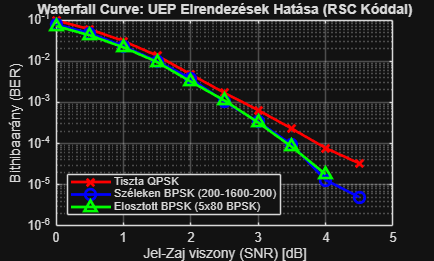


%% --- Eredmények kirajzolása ---
figure('Name', 'UEP Stratégiák Versenye (RSC kódoló)', 'NumberTitle', 'off');
semilogy(snr_dB_array, ber_qpsk, 'r-x', 'LineWidth', 2, 'MarkerSize', 8); hold on;
semilogy(snr_dB_array, ber_edge, 'b-o', 'LineWidth', 2, 'MarkerSize', 8);
semilogy(snr_dB_array, ber_distr, 'g-^', 'LineWidth', 2, 'MarkerSize', 8);
grid on;
title('Waterfall Curve: UEP Elrendezések Hatása (RSC Kóddal)');
xlabel('Jel-Zaj viszony (SNR) [dB]');
ylabel('Bithibaarány (BER)');
legend('Tiszta QPSK', 'Széleken BPSK (200-1600-200)', 'Elosztott BPSK (5x80 BPSK)', 'Location', 'southwest');